# Pràctica 10

### Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

Trobar les imatge amb samarretes del Barça a partir d'una imatge model.

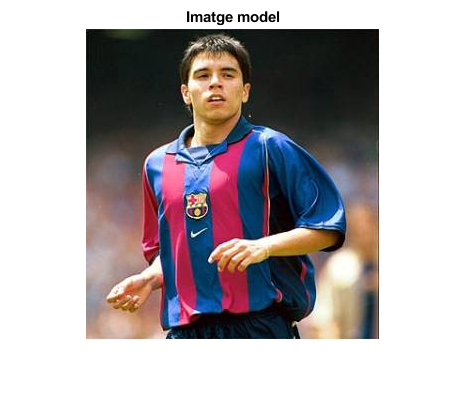

im = imread('team1.jpg');
figure, imshow(im), title('Imatge model')

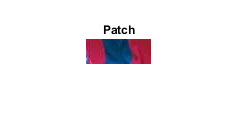

aux = im(248:272,92:156,:);
imshow(aux), title('Patch')

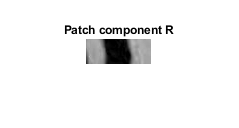

rb = NormalitzaRGB(im);
rb = rb(248:272,92:156,:);
figure, imshow(rb(:,:,1)), title('Patch component R')

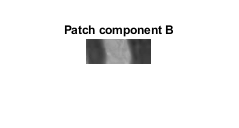

figure, imshow(rb(:,:,2)), title('Patch component B')

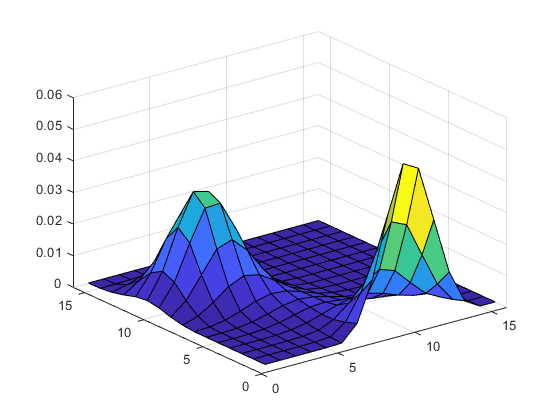

h1 = histo2D(rb,16);
h1 = imgaussfilt3(h1, 1.5);
figure,surf(h1)

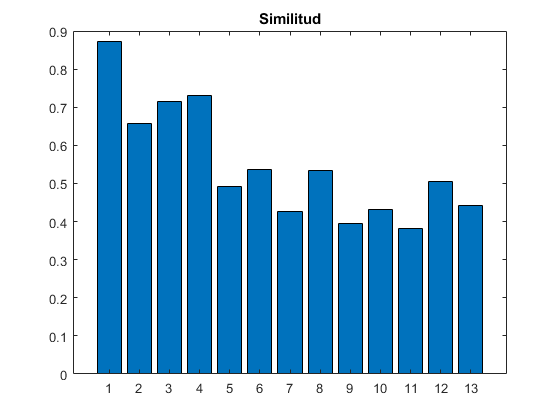


sim = zeros(13, 1);
Npatches = 100;
for i = 1:13
    im = imread(sprintf('team%d.jpg', i));
    rb = NormalitzaRGB(im);
    S = 0;
    for j = 1:Npatches
        rb2 = patch_aleatori(rb, 25, 65);
        h = histo2D(rb2, 16);
        h = imgaussfilt3(h, 1.5);
        aux = min(h1, h);
        S = max(S, sum(aux(:)));
    end
    sim(i) = S;
end
figure, bar(sim), title('Similitud')

## Funcions

#### NormalitzaRGB.m

type NormalitzaRGB.m


function [rb] = NormalitzaRGB(im)
    [files cols ch] = size(im);
    im = double(im);
    sum = im(:,:,1) + im(:,:,2) + im(:,:,3);
    rb = uint8(zeros(files, cols,2));
    rb(:,:,1) = uint8(255*im(:,:,1)./sum);
    rb(:,:,2) = uint8(255*im(:,:,3)./sum);
end



### histo2D.m

type histo2D.m


function [h1] = histo2D(image,nbins)
    h1 = zeros(nbins);
    [rows cols ~] = size(image);
    for i = 1:rows
        for j = 1:cols
            x = floor(double(image(i,j,1))/nbins) + 1;
            y = floor(double(image(i,j,2))/nbins) + 1;
            h1(x,y) = h1(x,y)+1;
        end
    end
    h1 = h1./(rows*cols);
end



### get_random_number.m

type get_random_number.m


function [num] = get_random_number(min,max)
    num = ceil((max-min).*rand(1) + min);
end



### patch_aleatori.m

type patch_aleatori.m


function [patch] = patch_aleatori(image, sX, sY)
    [files cols ~] = size(image);
    X = get_random_number(1, files - sX);
    Y = get_random_number(1, cols - sY);
    
    patch = image(X:(X+sX), Y:(Y+sY), :);
end

